**Pr 1**. Sa se gaseasca aproximanta discreta prin metoda celor mai mici patrate

pentru ponderea w(x)=1 si baza 1; x; x^2; : : : ; x^n:

X = 1:10;
Y = sin(X);

%datele ce urmeaza a fi aproximate
x = X(1):(X(end)-X(1))/100:X(end)

x =     1.0000    1.0900    1.1800    1.2700    1.3600    1.4500    1.5400    1.6300    1.7200    1.8100    1.9000    1.9900    2.0800    2.1700    2.2600    2.3500    2.4400    2.5300    2.6200    2.7100    2.8000    2.8900    2.9800    3.0700    3.1600    3.2500    3.3400    3.4300    3.5200    3.6100    3.7000    3.7900    3.8800    3.9700    4.0600    4.1500    4.2400    4.3300    4.4200    4.5100    4.6000    4.6900    4.7800    4.8700    4.9600    5.0500    5.1400    5.2300    5.3200    5.4100


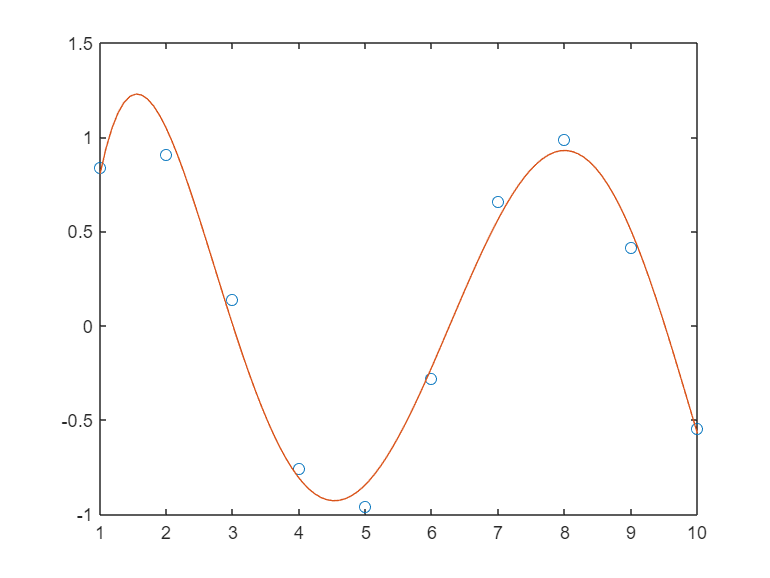


y = mcmmp_discreta(x, X, Y, 5);

plot(X, Y, 'o', x, y, '-');

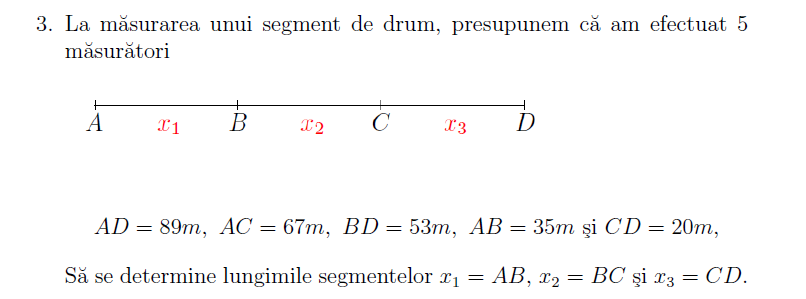

% x1 + x2 + x3 = 89
% x1 + x2 = 67
% x2 + x3 = 53
% x1 = 35
% x3 = 20
X = [1 1 1; 
    1 1 0; 
    0 1 1; 
    1 0 0; 
    0 0 1];
Y = [89; 67; 53; 35; 20];

a = X \ Y;
AB = a(1,1);
BC = a(2,1);
CD = a(3, 1);
fprintf("AB  x1 = %7.2f, BC  x2 = %7.2f, CD x3 = %7.2f", AB, BC, CD);

AB  x1 =   35.12, BC  x2 =   32.50, CD x3 =   20.62

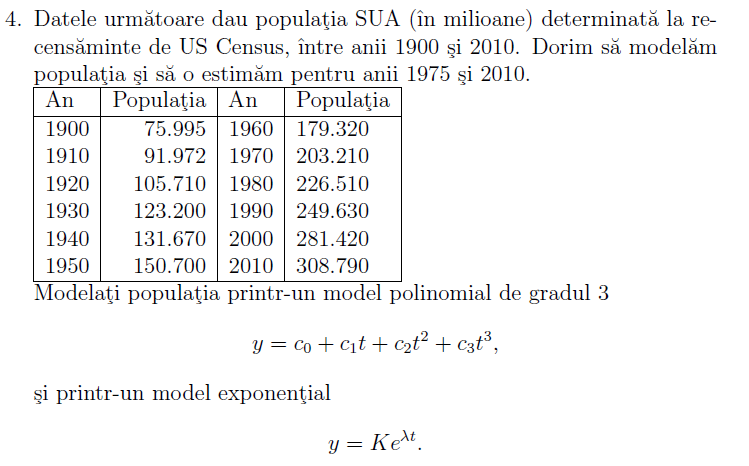

% Potrivire polinomială:
y = [75995 91972 105710 123200 131670 150700 179320 203210 226510 249630 281420 308790]';
t = (1900:10:2010)';
x = (1890:1:2019)';
w = 1975 

w = 1975

fprintf("Potrivire polinomială:");

Potrivire polinomială:

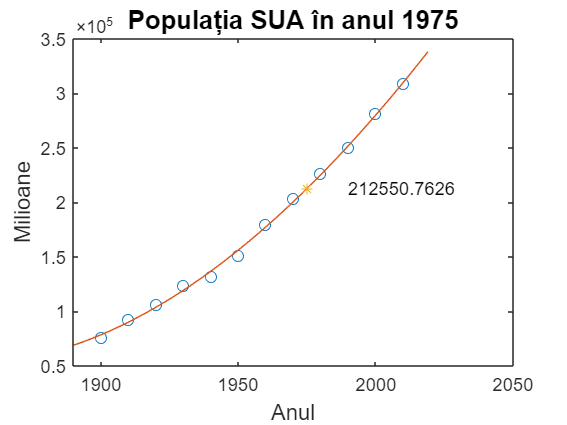


s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3); % primesc coef
zs = polyval(cs, xs); % eval pt cs
est = polyval(cs, (1975 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 1975", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);

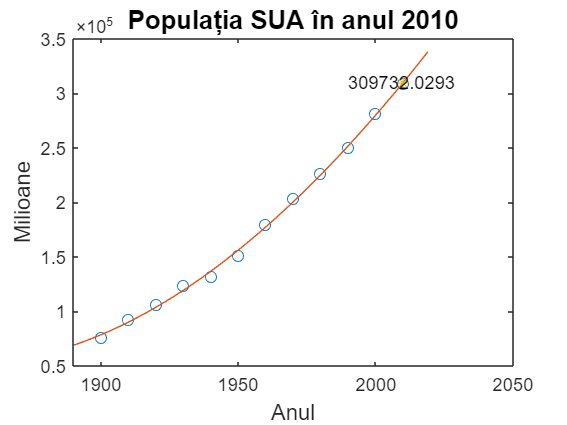


w = 2010;

s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, (2010 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 2010", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);